% (C) Copyright 2020 Murilo Marques Marinho
%
%     This file is licensed in the terms of the
%     Attribution-NonCommercial-ShareAlike 4.0 International (CC BY-NC-SA 4.0) 
%     license.
%
% Contributors to this file:
%     Murilo Marques Marinho - murilo@nml.t.u-tokyo.ac.jp
clear all;
close all;

# Dual Quaternion Basics using DQ Robotics - Part 2

## Introduction

The last lesson introduced dual quaternions, some basic dual quaternion operations; and, most importantly, unit dual quaternions and their ability to represent rigid body motion.

As always, before we start, let us add the namespace to our workspace.

%% Include the DQ Robotics namespace. Probably a good idea to add to all scripts.
include_namespace_dq

## Notation

In the last lesson, we learned that unit dual quaternions represent reference frames and pose transformations. In this lesson, we will see that dual quaternions can also represent points, lines, and planes.

Keep these in mind (we will also use this notation when writting papers to conferences and journals):

- $\mathit{\mathbf{h}}\in$$\mathbb{H}$: a quaternion. (Bold-face, lowercase character)

- $\underline{\mathit{\mathbf{h}}} \in$$\mathcal{H}$: a dual quaternion. (Bold-face, underlined, lowercase character)

- $\mathit{\mathbf{p}},\mathit{\mathbf{t}}\in$$$\mathbb{H}_p$$: points, positions, and translations. Quaternions for which $\textrm{Re}\left(\mathit{\mathbf{h}}\right)=0\ldotp$

- $\mathit{\mathbf{r}}\in$$\mathbb{S}^3$: orientations and rotations. Quaternions for which $\left|\right|\mathit{\mathbf{h}}\left|\right|=1$. 

- $\underline{\mathit{\mathbf{x}}}$ $\in$$\underline{\bf{\mathcal{S}}}$: poses and pose transformations. Dual quaternions for which $\left|\right|\underline{\mathit{\mathbf{h}}} \left|\right|=1$.

## What we have seen so far

### Points, positions, and translations

A pure quaternion, such as $\mathit{\mathbf{p}},\mathit{\mathbf{t}}\in$$$\mathbb{H}_p$$, can be used to represent points, positions, and translations. Pure quaternions can be always written in the form


$$\mathit{\mathbf{t}}=x\hat{\i \;} +y\hat{\j \;} +z\hat{k} ,$$


where $x,y,z\in$$\mathbb{R}$ represent the 3D coordinates.

### Orientations and rotations

A unit quaternion, $\mathit{\mathbf{r}}\in$$\mathbb{S}^3$, can always be written in the form


$$\mathit{\mathbf{r}}=\cos \left(\frac{\phi \;}{2}\right)+\mathit{\mathbf{v}}\ldotp \sin \left(\frac{\phi \;}{2}\right),$$


where $\phi \in$$\mathbb{R}$ represents the rotation angle and $\mathit{\mathbf{v}}\in$ $$\mathbb{H}_p$$ represents the rotation axis.

### Reference frames and pose transformations

A unit dual quaternion, $\underline{\mathit{\mathbf{x}}}$ $\in$$\underline{\bf{\mathcal{S}}}$, can always be written in the form


$$\underline{\mathit{\mathbf{x}}} =\mathit{\mathbf{r}}+\varepsilon \frac{\;1}{2}\mathit{\mathbf{t}}\ldotp \mathit{\mathbf{r}},$$


where $\mathit{\mathbf{r}}\in$$\mathbb{S}^3$ is the unit-norm quaternion representing the rotation; and $\bf{t}$ $\in \mathbb{H}_p$ is the quaternion representing the translation. 

## Lines and planes

Unit dual quaternions, besides being used to represent rotations and translations, can also be used to represent lines and planes in 3D space. These geometric primitives are very useful in many robot control scenarios. 

### Plücker Lines

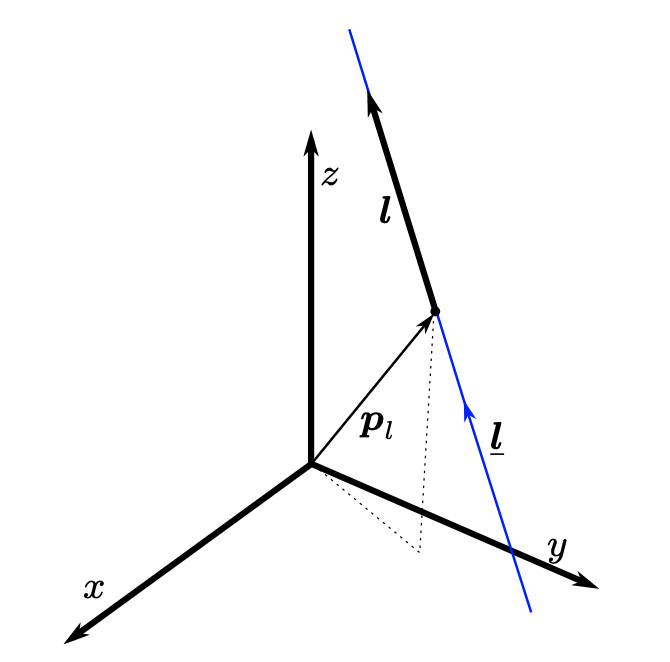

In high-school, you have been introduced to the line equation in 3D space using linear algebra. Using the concept of unit dual quaternions, we can also represent lines, in the form


$$\underline{\mathit{\mathbf{l}}} =\mathit{\mathbf{l}}+\varepsilon \mathit{\mathbf{m}},$$


where $\mathit{\mathbf{l}}\in$ $\mathbb{H}_p \cap \mathbb{S}^3$ is a unit vector representing the line's direction and $\mathit{\mathbf{m}}\in$$\mathbb{H}_p$ is called the line's moment. The moment is defined as $\mathit{\mathbf{m}}$$\triangleq$${\mathit{\mathbf{p}}}_l \times \mathit{\mathbf{l}}$, in which ${\mathit{\mathbf{p}}}_l \in$$\mathbb{H}_p$ is a point (any point) in the line. A line represented this way is called a Plücker line. Note that a Plücker line is a pure dual quaternion with unit norm, that is $\underline{\bf{l}}\in \mathcal{H}_p\cap\mathcal{\underline{\bf{S}}}$.

#### Pure quaternion cross product

Note that $\times \;$is the cross product between pure quaternions, and is defined as


$${\mathit{\mathbf{h}}}_1 \times {\mathit{\mathbf{h}}}_2 =\frac{\;{\mathit{\mathbf{h}}}_1 {\mathit{\mathbf{h}}}_2 -{\mathit{\mathbf{h}}}_2 {\mathit{\mathbf{h}}}_1 }{2}$$


for any ${\mathit{\mathbf{h}}}_1 ,{\mathit{\mathbf{h}}}_2 \in$$\mathbb{H}_p$. Note that this operation is equivalent to the cross product between vectors in $\mathbb{R}^3$.

#### Plücker line example

Suppose that we want the Plücker line that represents the x-axis. The direction of the line will be


$${\mathit{\mathbf{l}}}_1 =\hat{\i \;}$$


l1=i_

l1 = 
         1i


and a point in the line is

${\mathit{\mathbf{p}}}_{l,1} =0\hat{\i \;} +0\hat{\j \;} +0\hat{k} =0$,

p_l1 = DQ(0) % We use the DQ() constructor so that MATLAB knows its a DQ, not a real number.

p_l1 = 
         0


because the line crosses the origin. Hence, the moment of the line will be given by


$${\mathit{\mathbf{m}}}_1 ={\mathit{\mathbf{l}}}_1 \times {\mathit{\mathbf{p}}}_{l,1}$$


m1 = cross(l1,p_l1)

m1 = 
         0


Hence, the Plücker line representing the origin will be


$${\underline{\mathit{\mathbf{l}}} }_1 ={\mathit{\mathbf{l}}}_1 +\varepsilon {\mathit{\mathbf{m}}}_1 =\hat{\i \;} \ldotp$$


l1_dq = l1 + E_*m1

l1_dq = 
         1i


#### Checking if a dual quaternion is a line using DQ Robotics

Let us check that the Plücker line we calculated is a pure dual quaternion with unit norm. The following two conditions have to hold simultaneously.

is_pure(l1_dq)

ans = 1

is_unit(l1_dq)

ans = 1

You can also test directly if those two conditions hold simultaneously with

is_line(l1_dq)

ans = 1

#### Plotting lines using DQ Robotics

When you plot lines using DQ Robotics you have to specify that you want to plot that unit dual quaternion as a line. For example

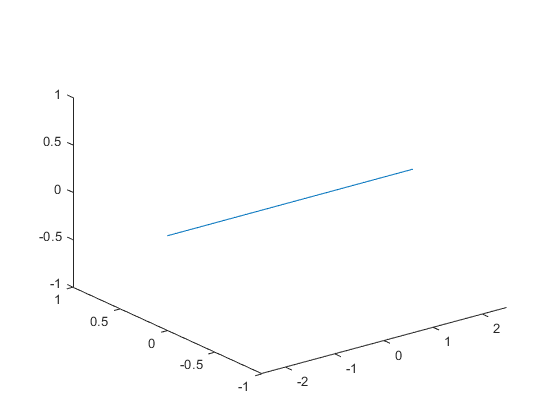

plot(l1_dq,'line', 5); 

***Note that a Plücker line is, well, a line (not a line segment). This means that, mathematically, its length is infinite. When plotting, you have to choose how much of the line you want to show on screen. In this example, we are showing 5 meters only. ***

### Planes

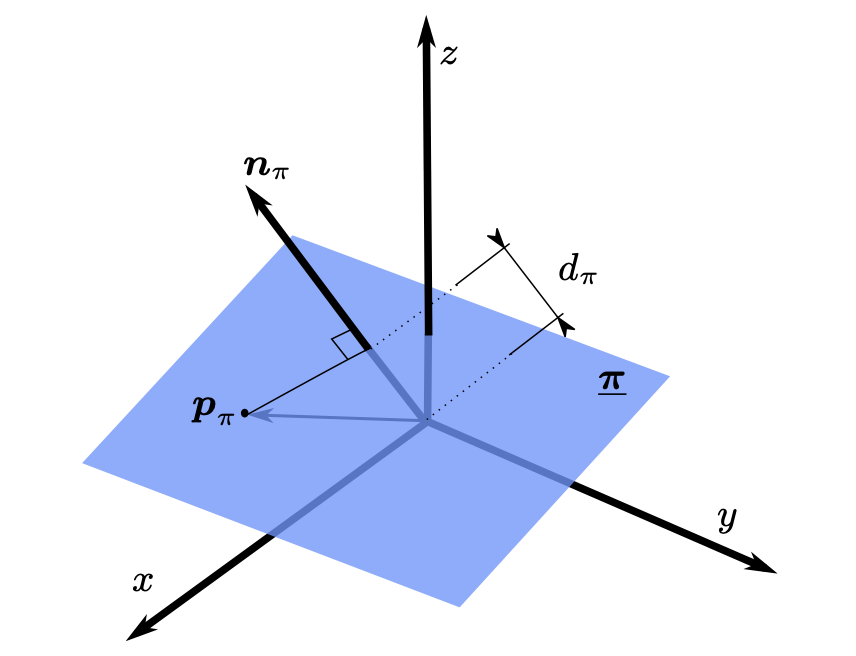

Also in high-school-level linear-algebra, you have been introduced to the equation of the plane. Unit dual quaternions can also be used to represent planes, in the form


$$\pi_‾ ={\mathit{\mathbf{n}}}_{\pi \;} +\varepsilon d_{\pi \;} ,$$


where ${\mathit{\mathbf{n}}}_{\pi \;} \in$$\mathbb{H}_p \cap \mathbb{S}^3$ is the unit vector representing the plane's normal. In addition, $d_{\pi \;} \in$$\mathbb{R}$ is the signed distance to the plane (with respect to the normal centered at the origin), that can be written as


$$d_{\pi \;} =\;<{\mathit{\mathbf{p}}}_{\pi \;} ,{\mathit{\mathbf{n}}}_{\pi \;} >$$


in which  ${\mathit{\mathbf{p}}}_{\pi \;\;} \in$$\mathbb{H}_p$ is any point in the plane.

#### Pure quaternion inner product

Note that $<,>\;$is the inner product between pure quaternions, and is defined as


$$<{\mathit{\mathbf{h}}}_{1,} {\mathit{\mathbf{h}}}_2 >=-\frac{\;{\mathit{\mathbf{h}}}_1 {\mathit{\mathbf{h}}}_2 +{\mathit{\mathbf{h}}}_2 {\mathit{\mathbf{h}}}_1 }{2}$$


for any ${\mathit{\mathbf{h}}}_1 ,{\mathit{\mathbf{h}}}_2 \in$$\mathbb{H}_p$.

#### Plane example

Suppose that we want one of the unit dual quaternions that represents the x-y plane. One of the normals to the x-y plane (there are two), is given by


$${\mathit{\mathbf{n}}}_{\pi ,1} =\hat{k}$$


n_pi1 = k_

n_pi1 = 
         1k


One of the points in the x-y plane is the origin, so we can use


$${\mathit{\mathbf{p}}}_{\pi ,1} =0$$


p_pi1 = DQ(0)  % We use the DQ() constructor so that MATLAB knows its a DQ, not a real number.

p_pi1 = 
         0


Hence, the distance can be calculated as


$$d_{\pi ,1} =\;<{\mathit{\mathbf{p}}}_{\pi ,1} ,{\mathit{\mathbf{n}}}_{\pi ,1} >\;=0$$


d_pi1 = dot(p_pi1, n_pi1)

d_pi1 = 
         0


Therefore, the x-y plane can be represented by the unit dual quaternion


$${\pi_‾ }_1 ={\mathit{\mathbf{n}}}_{\pi ,1} +\varepsilon d_{\pi ,1} =\hat{k} \ldotp$$


pi1 = n_pi1 + E_*d_pi1

pi1 = 
         1k


#### Checking if a dual quaternion is a plane using DQ Robotics

We can check if a unit dual quaternion represents a plane if all the following conditions hold simultaneously.

is_unit(pi1)

ans = 1

is_pure(P(pi1))

ans = 1

is_real(D(pi1))

ans = 1

This can be done directly with one command

is_plane(pi1)

ans = 1

#### Plotting planes using DQ Robotics

When you plot planes using DQ Robotics, you have to specify that you want to plot that unit dual quaternion as a plane. For example

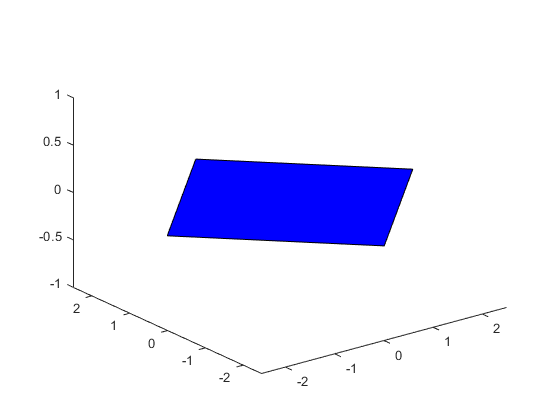

plot(pi1,'plane', 5, 'location', p_pi1); 

***Note that a plane line is, mathematically, infinite. When plotting, you have specify its size, in this case 5, and a central location, in this case ***${\mathit{\mathbf{p}}}_{\pi ,1}$***. ***

## (Signed) distances

One important measure for controlling robotic systems is the measurement of distance. The distance is always a real number. In some contexts it might be signed. We will discuss some of those cases.

### Point to point distance

The distance between two points is the most basic form of distance. Given ${\mathit{\mathbf{p}}}_1 ,{\mathit{\mathbf{p}}}_2 \in$$$\mathbb{H}_p$$, the distance between them is given by


$$d_{p_1 ,p_2 } =\left|\right|{\mathit{\mathbf{p}}}_1 -{\mathit{\mathbf{p}}}_2 \left|\right|$$


For example, using DQ Robotics, this can be calculated as,

p1 = i_+j_;
p2 = k_;
d_p1_p2 = norm(p1-p2)

d_p1_p2 = 
         1.7321


### Point to line distance

The distance between any point $\mathit{\mathbf{p}}\in$$$\mathbb{H}_p$$ and a line $\underline{\bf{l}}_1\in \mathcal{H}_p\cap\mathcal{\underline{\bf{S}}}$ is


$$d_{p,l_1 } =\left|\right|\mathit{\mathbf{p}}\times {\mathit{\mathbf{l}}}_1 -{\mathit{\mathbf{m}}}_1 \left|\right|$$


For example, using DQ Robotics, this can be calculated as,

% Point coordinates
p = i_+j_;
% Build the line
l1 = k_;
m1 = cross(i_,k_);
l1_dq = l1 + E_*m1;
% Calculate distance
d_p_l1 = norm(cross(p,l1)-m1)

d_p_l1 = 
         1


The distance can also be calculated in using a dedicated function inside DQ_Geometry.

d_p_l1 = sqrt(DQ_Geometry.point_to_line_squared_distance(p,l1_dq))

d_p_l1 = 1

***Note: when controlling robots, it is usually more convenient to use the squared norm instead of the norm.***

### Point to plane signed distance

The (signed) distance between a point $\mathit{\mathbf{p}}\in$$$\mathbb{H}_p$$ and a plane ${\pi_‾ }_1$, with respect to the plane, is


$$d_{p,\pi {\;}_1 } =\;<\mathit{\mathbf{p}},{\mathit{\mathbf{n}}}_{\pi \;,1} >-d_{\pi \;,1} \ldotp$$


Note that the sign of the distance indicates if the point is "above" the plane or "below" the plane.

For example, using DQ Robotics, this can be calculated as,

% Point coordinates
p = k_;
% Build the plane
n_pi1 = k_;
p_pi1 = DQ(0);
d_pi1 = dot(p_pi1,n_pi1);
pi1 = n_pi1 + E_*d_pi1;
% Calculate distance
d_p_pi1 = dot(p,n_pi1)-d_pi1

d_p_pi1 = 
         1


This distance can also be calculated with

d_p_pi1 = DQ_Geometry.point_to_plane_distance(p,pi1)

d_p_pi1 = 1

### Line to line distance

Calculating the distance between two lines, $\underline{\bf{l}}_1, \underline{\bf{l}}_2 \in \mathcal{H}_p\cap\mathcal{\underline{\bf{S}}}$ is somewhat more complicated than the ones mentioned above so we will skip the details for now. You can check the following paper for details:

[**Dynamic Active Constraints for Surgical Robots using Vector Field Inequalities. **](https://arxiv.org/pdf/1804.11270.pdf)Marinho, M. M; Adorno, B. V; Harada, K.; and Mitsuishi, M. *IEEE Transactions on Robotics (T-RO)*, 35(5): 1166–1185. October 2019.  

For now, it suffices to know that the distance between two lines can be obtained, using DQ Robotics, as follows

% Build l1_dq
l1 = k_;
p_l1 = DQ(0);
m1 = cross(p_l1,k_);
l1_dq = l1 + E_*m1;
% Build l2_dq
l2 = k_;
p_l2 = i_;
m2 = cross(p_l2,k_);
l2_dq = l2 + E_*m2;
% Get the distance
d_l1_l2 = sqrt(DQ_Geometry.line_to_line_squared_distance(l1_dq,l2_dq))

d_l1_l2 = 1

# Homework

Following the template above to create a script called [dual_quaternion_basics_part2_homework.m], do the following.

- Find the Plücker line representing the y-axis using four different ${\mathit{\mathbf{p}}}_l$ and store them in ${\underline{\mathit{\mathbf{l}}} }_1 ,{\underline{\mathit{\mathbf{l}}} }_2 ,{\underline{\mathit{\mathbf{l}}} }_3 ,\textrm{and}\;{\underline{\mathit{\mathbf{l}}} }_4$. Are all Plücker lines the same?

- Define the point ${\mathit{\mathbf{p}}}_1 =2\hat{\i \;} +\hat{\j \;} +\hat{k}$ and calculate its distance to ${\underline{\mathit{\mathbf{l}}} }_1$.

- Find the y-z plane using the two possible plane normals, ${\mathit{\mathbf{n}}}_{\pi }$, and store them in ${\pi_‾ }_1$ and ${\pi_‾ }_2$.

- Calculate the distance between ${\mathit{\mathbf{p}}}_1$ and ${\pi_‾ }_1$, and between ${\mathit{\mathbf{p}}}_1$ and ${\pi_‾ }_2$. Are the signs different? Why?

- Build a 5mx5mx5m cubic region centered in the origin delineated by 6 planes. Call them ${\pi_‾ }_3$, ${\pi_‾ }_4$, ${\pi_‾ }_5$, ${\pi_‾ }_6$, ${\pi_‾ }_7$, ${\pi_‾ }_8$. Make sure that all normals point towards the origin. Plot this cubic region.

- Among ${\pi_‾ }_3$, ${\pi_‾ }_4$, ${\pi_‾ }_5$, ${\pi_‾ }_6$, ${\pi_‾ }_7$, ${\pi_‾ }_8$, which one is the plane closest to ${\mathit{\mathbf{p}}}_1$? What is the distance between ${\mathit{\mathbf{p}}}_1$ and the closest plane?